J = [[-1 0];[0 4]]

J =     -1     0
     0     4


W = [[1 1];[0 2]]

W =      1     1
     0     2



A = inv(W).*J.*W

A =     -1     0
     0     4


\n \n \n
-------------------------------------
    -1     0
     0     4



V =      1     0
     0     1


D =     -1     0
     0     4


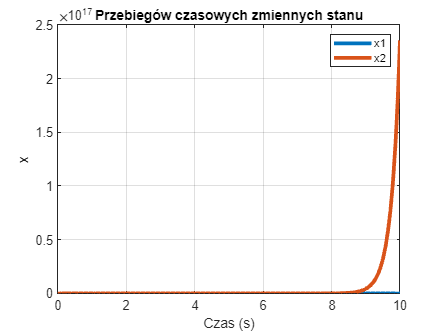

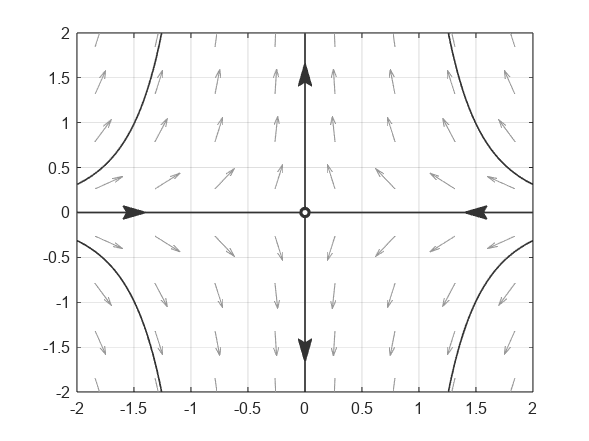

Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or
ALL functions to reduce operands to logical scalar values.

Error in kolo>lab1 (line 33)
if isreal(V) && D ~= 0


%lab1(A, [1, 1])

G1 = tf([1 2 4], [1 2 100])

G1 =
 
   s^2 + 2 s + 4
  ---------------
  s^2 + 2 s + 100
 
Continuous-time transfer function.



G2 = tf([0 50], [1 0])

G2 =
 
  50
  --
  s
 
Continuous-time transfer function.



G = G2*G1

G =
 
  50 s^2 + 100 s + 200
  --------------------
  s^3 + 2 s^2 + 100 s
 
Continuous-time transfer function.




k = -0.96;
pole(k*G/(k*G+1))

ans =    0.0000 + 0.0000i
  46.0038 + 0.0000i
  -1.0000 + 9.9499i
  -1.0000 - 9.9499i
  -0.0019 + 2.0429i
  -0.0019 - 2.0429i



figure
%nyquist(G)


function [] = lab1(A, x0)
disp("\n \n \n")
disp("-------------------------------------")
disp(A)
[V, D] = eig(A)
%Krok 2
tmax = 10 ;
[ t , x ] = ode45 (@( t , x ) A*x , [0 tmax] , x0 ) ;
figure
plot( t, x, "LineWidth" ,3 );
grid on; hold all ;
xlim( [0 tmax] );
%ylim([-5 5]);
legend( "x1" , "x2" , "Location" , "northeast" );
xlabel( "Czas (s)" );
ylabel( "x" );
title("Przebiegów czasowych zmiennych stanu")

%eigvec
[V, D] = eig(A);

hold on;
plotpp( @(t ,x) A*[x(1) ; x(2)] );
xlim([-2, 2]);
ylim([-2, 2]);

if isreal(V) && D ~= 0
    v1 = quiver(0, 0, V(1, 1), V(2, 1), 'Linewidth', 3); %wektor 1
    v2 = quiver(0, 0, V(1, 2), V(2, 2), 'Linewidth', 3); %wektor 2
else %if
    v1 = quiver(0, 0, 0, 0, 'Linewidth', 0.01); %wektor 1
    v2 = quiver(0, 0, 0, 0, 'Linewidth', 0.01); %wektor 2
    disp("Complex eigenvectors");
end %if

title("Portret fazowy")

%Krok 3
tr = Krok3(A, 4);

p = scatter(0, 0, 20, "red", "filled"); % punkt równowagi

legend([v1, v2, p, tr], ["Wektor Własny 1", "Wektor Własny 2", "Punkt równowagi", "Trajektorie fazowe"])
end %function

function [tr] = Krok3(A, scale)
i_n = linspace(0, 2*pi, 4) + pi/12; 
[V, D] = eig(A);
i_n(4) = atan(V(1,1)/V(2,1));
i_n(5) = atan(V(1,2)/V(2,2));
%figure;
%hold on;
%grid on;
for i = i_n
    x0_n = [scale*cos(i), scale*sin(i)];
    scatter(x0_n(1), x0_n(2), "blue", "filled");
    tmax = 10;
    [ t , x ] = ode45 (@( t , x ) A*x , [0 tmax] , x0_n ) ;
    
    tr = plot(x(:, 1), x(:, 2), Color='b', LineWidth=0.2);

end %for

end %function
